# Estadística: La venganza >:v

## Importar datos

load("../Utils4SP/Datasets/S5_Estadistica101_LaVenganza.mat");

## Unos primeros plots

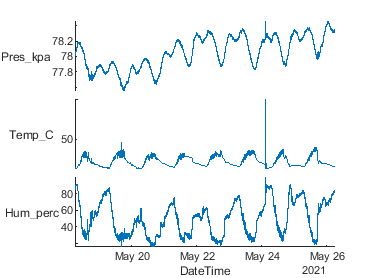

figure
% Staked plot --> Gráfica los datos unos sobre otros
stackedplot(atmosfera,"XVariable","DateTime")

## Exploración de los datos


% Obtenemos el resumen de los datos
summary(atmosfera)

Variables:

    Fecha: 137522×1 cell array of character vectors

    Hora: 137522×1 cell array of character vectors

    Pres_kpa: 137522×1 double

        Values:

            Min        77.55  
            Median     78.06  
            Max        78.46  

    Temp_C: 137522×1 double

        Values:

            Min             13.38  
            Median          21.01  
            Max             100    
            NumMissing      11     

    Hum_perc: 137522×1 double

        Values:

            Min             15.27  
            Median          50.16  
            Max             99.97  
            NumMissing      61     

    DateTime: 137522×1 datetime

        Values:

            Min       20210518 06:00:03
            Median    20210522 05:59:48
            Max       20210526 05:59:55



% Pedimos que nos muestren los datos donde les falte el campo
% .. de humedad.

atmosfera(ismissing(atmosfera.Hum_perc),:)

ans = 61×6 table
      Fecha           Hora        Pres_kpa    Temp_C    Hum_perc        DateTime     
    __________    ____________    ________    ______    ________    _________________

    {'210519'}    {'01:55:14'}     77.86      16.59       NaN       20210519 01:55:14
    {'210523'}    {'04:27:47'}      78.2      17.23       NaN       20210523 04:27:47
    {'210523'}    {'05:17:37'}      78.2       17.2       NaN       20210523 05:17:37
    {'210524'}    {'02:32:46'}     78.38        100       NaN       20210524 02:32:46
    {'210524'}    {'02:32:56'}     78.38        100       NaN       20210524 02:32:56
    {'210524'}    {'02:33:06'}     78.38        100       NaN       20210524 02:33:06
    {'210524'}    {'02:33:11'}     78.38        100       NaN       20210524 02:33:11
    

% Ahora pedidmos los datos tl que tengan la columna de temperatura
% ... faltante, y de esos regresamos los datos de tiempo y humedad.

atmosfera(ismissing(atmosfera.Temp_C),["DateTime" "Hum_perc"])

ans = 11×2 table
        DateTime         Hum_perc
    _________________    ________

    20210518 17:59:58     49.68  
    20210520 09:27:14     38.97  
    20210520 09:37:27     39.47  
    20210520 21:22:43     44.84  
    20210521 20:50:27     48.07  
    20210522 20:57:34     51.34  
    20210522 20:57:44     51.21  
    20210522 20:58:39     51.29  
    20210523 10:19:08     53.71  
    20210523 21:44:54     52.82  
    20210525 18:14:48     61.06  


## Limpieza de datos

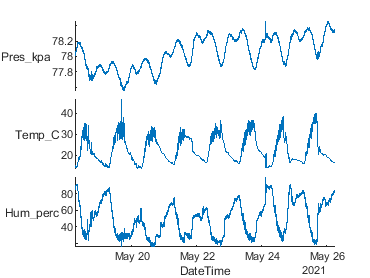

% Hora de quitar los NaNs

atmosfera_clean=rmmissing(atmosfera);

figure
stackedplot(atmosfera_clean,"XVariable","DateTime")


% Visualmente no notamos mucha diferencia, pero ahora deberiamos
% .. de tener unos datos bien limpios.

## Metricas

hum_promedio = mean(atmosfera_clean.Hum_perc)

hum_promedio = 49.6841

hum_mediana  = median(atmosfera_clean.Hum_perc)

hum_mediana = 50.1550

hum_moda     = mode(atmosfera_clean.Hum_perc)

hum_moda = 28.9200


% Calculando los cuartiles
hum_1Q = quantile(atmosfera_clean.Hum_perc,0.25)

hum_1Q = 29.8800

hum_3Q = quantile(atmosfera_clean.Hum_perc,0.75)

hum_3Q = 66.9600

% Métricas en el histograma

figure
tiledlayout(1,2)
nexttile
boxplot(atmosfera_clean.Hum_perc)

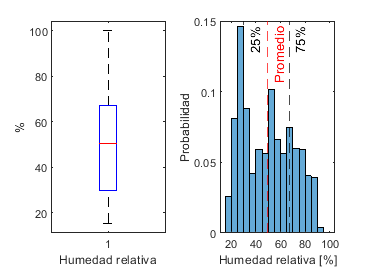

xlabel("Humedad relativa")
ylabel("%")

% Pasamos a la siguiente gráfica del arrange.
nexttile
histogram(atmosfera_clean.Hum_perc,"BinWidth",5,"Normalization","probability")
hold on

% Aquí vienen las métricas
xline(hum_promedio,"--r","Promedio")
xline(hum_1Q,"--k","25%")
xline(hum_3Q,"--k","75%")
hold off

xlabel("Humedad relativa [%]")
ylabel("Probabilidad")

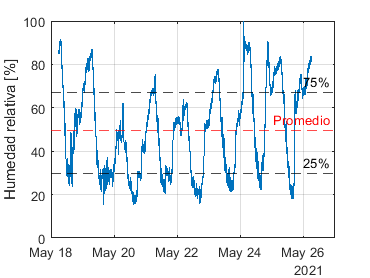

% Métricas en la serie de tiempo

figure
plot(atmosfera_clean.DateTime,atmosfera_clean.Hum_perc)
hold on
yline(hum_promedio,"--r","Promedio")
yline(hum_1Q,"--k","25%")
yline(hum_3Q,"--k","75%")
hold off


ylabel("Humedad relativa [%]")
grid on

grid minor % --> Hacemos el grid mas pequeño

## Medidas de Dispersión

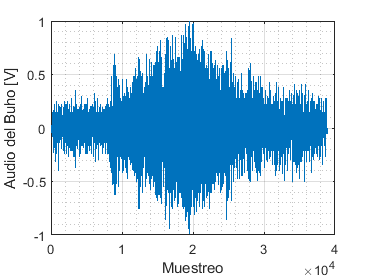

buho_left=buho(:,1);

% Visualizamos el audio del Buho.
figure
plot(buho_left)
ylabel("Audio del Buho [V]")
xlabel("Muestreo")
grid on
grid minor

% Calculamos la medidad de dispersión (Desviación estandar)

buho_var = var(buho_left)

buho_var = 0.0451

buho_std = std(buho_left)

buho_std = 0.2124

buho_promedio = mean(buho_left)

buho_promedio = 8.1547e-08

% Histograma y boxplot.

figure
tiledlayout(1,2)
nexttile
boxplot(buho_left)

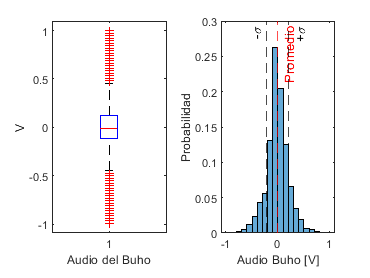

xlabel("Audio del Buho")
ylabel("V")

nexttile
histogram(buho_left,20,"Normalization","probability")
xline(buho_promedio,"--r","Promedio")
xline(buho_promedio+buho_std,"--k","+\sigma")
xline(buho_promedio-buho_std,"--k","-\sigma","LabelHorizontalAlignment","Left")
xlabel("Audio Buho [V]")
ylabel("Probabilidad")

## Regresión

% Realizamos las regresiones

% Regresión de grado 1 --> Regresión lineal
[fit_relacion,gof]  = fit(atmosfera_clean.Temp_C,atmosfera_clean.Hum_perc,"poly1")

fit_relacion =      Linear model Poly1:
     fit_relacion(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      -2.772  (-2.781, -2.763)
       p2 =       113.2  (112.9, 113.4)

gof = struct with fields:
           sse: 1.5967e+07
       rsquare: 0.7212
           dfe: 137448
    adjrsquare: 0.7212
          rmse: 10.7783



% Regresión de grado 2 --> Regresión polinómica de grado 2
[fit_relacion_2,gof] = fit(atmosfera_clean.Temp_C,atmosfera_clean.Hum_perc,"poly2")

fit_relacion_2 =      Linear model Poly2:
     fit_relacion_2(x) = p1*x^2 + p2*x + p3
     Coefficients (with 95% confidence bounds):
       p1 =       0.088  (0.08654, 0.08946)
       p2 =      -7.097  (-7.169, -7.024)
       p3 =       162.6  (161.8, 163.5)

gof = struct with fields:
           sse: 1.4498e+07
       rsquare: 0.7468
           dfe: 137447
    adjrsquare: 0.7468
          rmse: 10.2703


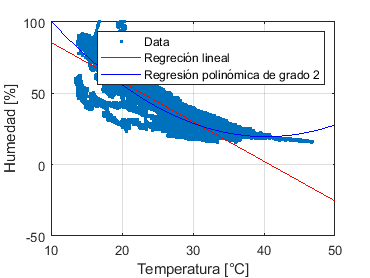


figure
plot(atmosfera_clean.Temp_C,atmosfera_clean.Hum_perc,".")
hold on
plot(fit_relacion,"r")
plot(fit_relacion_2,"b")
hold off
xlabel("Temperatura [°C]")
ylabel("Humedad [%]")
legend("Data","Regreción lineal","Regresión polinómica de grado 2")
grid on